**Annotated live script for EchoBot data processing** 

Emmett Culhane 

11/09/2025

The goal of this script is to produce and evaluate the ts(f) interference pattern for standard targets observed by EchoBot in CRL tank testing. We are working towards building an end-to-end process for raw EchobBot voltages to key metrics inclusing target location / range, mean ts, ts(f) and the SNR. 

Testing files come from one of three tank deployments on 09/04, 10/15 and 11/05. Operating parameters associated with each testing file are given above the string definitions. 

% Load file: 

clear all; 

%-------Emmett + Jennifer + Bob CRL tests from 09/04/2025

% 09/04/2025 || 38 & 22mm targets || 3 dB || stationary target || downsweep
file = 'C:\Users\emmett.culhane\Desktop\EchoBot\backcyl_bis_rgh0.01271_T143330_100.mat';

% 09/04/2025 || 38 & 22mm targets || 3 dB || stationary target || upsweep
% file = 'C:\Users\emmett.culhane\Desktop\EchoBot\backcyl_bis_rgh0.01271_T151206_100.mat'; 


%-------Bob CRL tests from 10/15/2025

% 22mm single target || 0 dB || stationary target || upsweep
% file = 'C:\Users\emmett.culhane\Desktop\EchoBot\backcyl_bis_rgh0.01271_T110424_100.mat'; 

% 22mm single target || 3 dB || stationary target || upsweep
% file = 'C:\Users\emmett.culhane\Desktop\EchoBot\backcyl_bis_rgh0.01271_T110817_100.mat'; 


%-------Bob CRL tests from 11/05/2025

% 38mm single target || 3 dB || stationary target ||
% downsweep (poor quality)
% file = 'C:\Users\emmett.culhane\Desktop\EchoBot\backcyl_bis_rgh0.01271_T121721_020.mat'; 

% 38mm single target || 3 dB || moving target ||
% downsweep
% file = 'C:\Users\emmett.culhane\Desktop\EchoBot\backcyl_bis_rgh0.01271_T124029_100.mat'; 

% 38mm single target || 3 dB || moving target ||
% upsweep
% file = 'C:\Users\emmett.culhane\Desktop\EchoBot\backcyl_bis_rgh0.01271_T125313_100.mat';

% 22mm single target || 3 dB || moving target ||
% downsweep
% file = 'C:\Users\emmett.culhane\Desktop\EchoBot\backcyl_bis_rgh0.01271_T131215_100.mat'; 

% 22mm single target || 3 dB || moving target ||
% upsweep
% file = 'C:\Users\emmett.culhane\Desktop\EchoBot\backcyl_bis_rgh0.01271_T130710_100.mat';

% 22mm single target || -80 dB || stationary target || upsweep
% file = 'C:\Users\emmett.culhane\Desktop\EchoBot\backcyl_bis_rgh0.01271_T110817_100.mat'; 

Loading the file by string and extracting the required parameters from the header file. We define the sector channels (1, 2, 3), plotting axes, and build the transmit signal tx_ref. 

% Get parameters from header 
S = load(file);

% ---- Data & header ----
data   = S.data;      % [Ns x 5 x Npings]
header = S.header;
fs = header.fs;                                     % Hz
c  = isfield(header,'c')*header.c + ~isfield(header,'c')*1486;  % m/s
rx_chans = [1 2 3];                                  % sectors 1–3


% ---- Axes ----
Ns = size(data,1);
t  = (0:Ns-1).' / fs;  % s
R  = 0.5*c*(t - header.T_pre);      % <-- corrected raw-voltage range axis (to make MF and range/volt agree) % m

% ---- Tx reference chirp
T_chirp = numel(header.s_chirp)/fs; 
tx_ref = [zeros(round(header.T_pre*fs),1); header.s_chirp(:); zeros(round(header.T_post*fs),1)];

Here as a sanity check we plot the tx_ref chirp and make sure that it corresponds to our expectations based on CRL test documentation (see Notes for Bob Petit tests CRL1&2 and shown in-line above the file string definitions. 

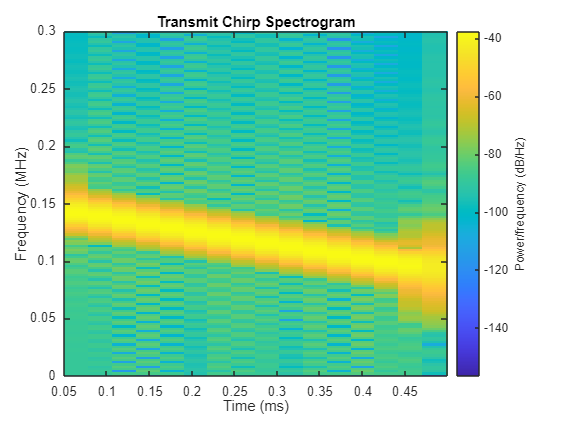

% Plot the chirp to see if it is the expected direction (e.g downsweep)
clf reset;
window = hamming(256);
T_chirp = numel(header.s_chirp)/fs; 
spectrogram(tx_ref, window, 200, 1024, fs, 'yaxis');
title('Transmit Chirp Spectrogram');

% 09/04/2025
xlim([0.05,0.5]);
ylim([0,0.3]);


% 10/15/2025
% xlim([0.25,0.85]);
% ylim([0,0.3]);

% 11/05/2025
% xlim([0.05,0.55]);
% ylim([0,0.3]);

We want to sample more than 1 ping, so here we are computing the maximum ping by stregth relative to the mean value, and then also getting the starting and ending index of the pings to check begin and end. 

% Get indices for
%   1) The 'strongest' ping
%   2) First ping
%   3) Last ping

Npings = size(data,3);
for p = 1:Npings
    s(p) = median(sqrt(mean(abs(data(:,:,p)).^2,1)));
end
start_idx = 1; 
end_idx = Npings; 
[~,max_idx] = max(s(2:end-1)); 
max_idx = max_idx + 1;
start_idx, end_idx, max_idx

start_idx = 1

end_idx = 100

max_idx = 59

Here we implement the matched filter processing code from Bob Petit replay_MF_modZ_CRL script, and plot the voltage time series. 

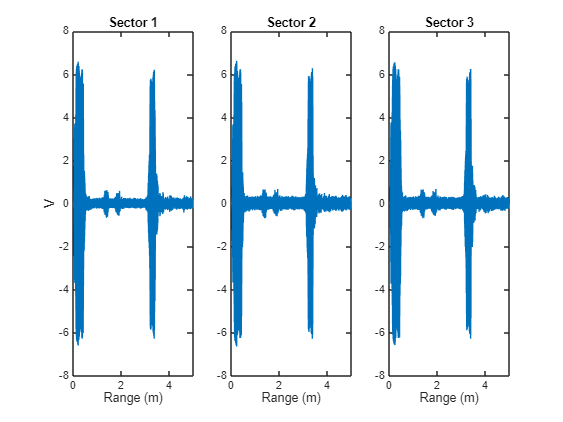

% Matched filter processing
ping_idx = start_idx;
clf reset; 
lp = designfilt('lowpassfir','PassbandFrequency',150e3,'StopbandFrequency',200e3, ...
                'PassbandRipple',1,'StopbandAttenuation',40,'SampleRate',fs);
hp = designfilt('highpassfir','PassbandFrequency',90e3,'StopbandFrequency',70e3, ...
                'PassbandRipple',1,'StopbandAttenuation',40,'SampleRate',fs);

df1 = filter(hp, filter(lp, data(:,1,ping_idx)));
df2 = filter(hp, filter(lp, data(:,2,ping_idx)));
df3 = filter(hp, filter(lp, data(:,3,ping_idx)));
[c1,l] = xcorr(df1,tx_ref); [c2,~] = xcorr(df2,tx_ref); [c3,~] = xcorr(df3,tx_ref);
idx = (l>=0);                                     % one common mask
Rmf = 0.5*c*(l(idx)/fs);                          % Nx1
C   = [c1(idx) c2(idx) c3(idx)];                  % Nx3
cc_dB = 20*log10(abs(hilbert(C))+eps);            % Nx3


% Plot the voltage time series (from Bob Petit replay code) 
Range = 0.5*c*(t - header.T_pre);
subplot(1,3,1); plot(Range,df1); xlim([0 5]); title('Sector 1'); xlabel('Range (m)'); ylabel('V')
subplot(1,3,2); plot(Range,df2); xlim([0 5]); title('Sector 2'); xlabel('Range (m)')
subplot(1,3,3); plot(Range,df3); xlim([0 5]); title('Sector 3'); xlabel('Range (m)')

Plot 3 sector MF in dB v range

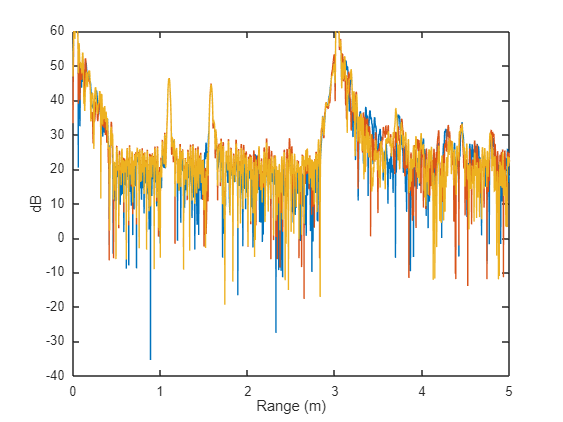

% Plot MF output dB v range 
clf reset;
plot(Rmf(:), cc_dB); xlim([0 5]); ylim([-40 60]); xlabel('Range (m)'); ylabel('dB');

Here we are hardcoding a noise range gate and a target gate, seeking maximum possible range around target peaks and using shallow, unoccupied water column sections as noise approximates. We plot the hardcoded gates to make sure they capture the target location effectively. 

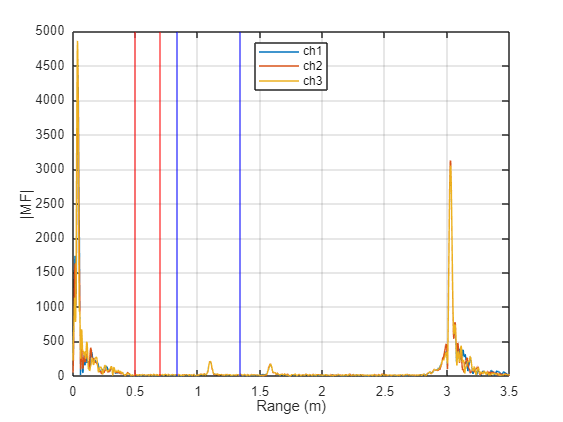

% Ok now lets plot the MF/range plot with FFT gates 
clf reset;


% ---- (0) Fixed range windows (hard-coded): CRL test 09/04/2025
% Noise location
near_center = 0.6; near_half = 0.1;   near_band = [near_center - near_half, near_center + near_half];

% Target locations
%   22mm sphere
far_center  = 1.09; far_half  = 0.25;   far_band  = [far_center  - far_half , far_center  + far_half ];
%   38mm sphere 
% far_center  = 1.57; far_half  = 0.25;   far_band  = [far_center  - far_half , far_center  + far_half ];



% ---- (1) Fixed range windows (hard-coded): CRL test 10/15/2025
% Noise location
% near_center = 0.6; near_half = 0.1;   near_band = [near_center - near_half, near_center + near_half];

% Target locations
%   22mm sphere
% far_center  = 1.14; far_half  = 0.3;   far_band  = [far_center  - far_half , far_center  + far_half ];



% ---- (2) Fixed range windows (hard-coded): CRL test 11/05/2025
% Noise location
% near_center = 0.6; near_half = 0.1;   near_band = [near_center - near_half, near_center + near_half];

% Target locations

%   38mm sphere (ext 721) 
% far_center  = 1.27; far_half  = 0.3;   far_band  = [far_center  - far_half , far_center  + far_half ];

%   22mm sphere (ext 710) 
% far_center  = 1.41; far_half  = 0.3;   far_band  = [far_center  - far_half , far_center  + far_half ];



% Plot
MFmag = abs(hilbert(C));                    % Nx3, envelope of MF per channel
plot(Rmf, MFmag); grid on; xlim([0 3.5]);   % |MF| vs range (all 3 sectors)
xlabel('Range (m)'); ylabel('|MF|');
xline(near_band(1),'r'); xline(near_band(2),'r');  % near gate
xline(far_band(1),'b');  xline(far_band(2),'b');   % far gate
legend('ch1','ch2','ch3','Location','best');

Using the gated regions take an FFT of the noise and the target and plot the ts(f) interference approximation for all three sectors. 

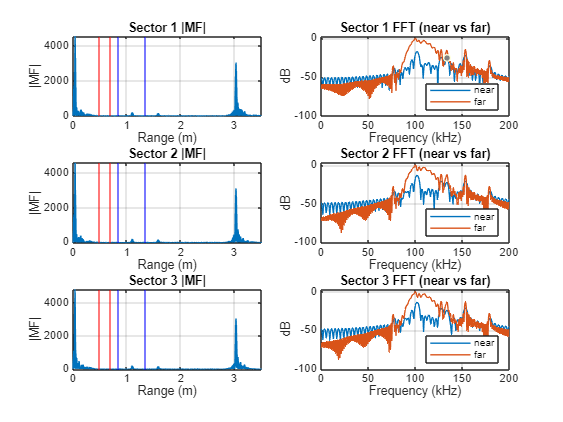

% Ok move on now to the final FFT process to build the approximate ts(f)
% visualizations
clf reset; 
Nfft = 4096;  f_Hz = (0:Nfft-1)*(fs/Nfft);

for ch = 1:3
    m = C(:,ch);                           % MF for this sector
    j0n = find(Rmf>=near_band(1),1); j1n = find(Rmf<=near_band(2),1,'last');
    j0f = find(Rmf>=far_band(1),1);  j1f = find(Rmf<=far_band(2),1,'last');
    FFTn = fft(m(j0n:j1n),Nfft);
    FFTf = fft(m(j0f:j1f),Nfft);
    SdB = 20*log10(abs([FFTn(:) FFTf(:)])./(max(abs([FFTn(:);FFTf(:)]))+eps));

    % left: |MF| vs range
    subplot(3,2,(ch-1)*2+1)
    plot(Rmf, abs(m)); hold on
    xline(near_band(1),'r'); xline(near_band(2),'r');
    xline(far_band(1),'b');  xline(far_band(2),'b');
    xlim([0 3.5]); grid on
    title(['Sector ' num2str(ch) ' |MF|'])
    xlabel('Range (m)'); ylabel('|MF|')

    % right: FFT spectra (near/far)
    subplot(3,2,(ch-1)*2+2)
    plot(f_Hz/1e3, SdB, 'LineWidth',1)
    grid on; xlim([0 200]); ylim([-100 3])
    xlabel('Frequency (kHz)'); ylabel('dB')
    title(['Sector ' num2str(ch) ' FFT (near vs far)'])
    legend('near','far','Location','best')
end